# **Sesion 2.3.- Creación de un robot con RigidBodyTree: diferencias**

El objetivo de esta sesión es crear un robot ABB IRB120 utilizando el rigidBodyTree de Matlab, utilizando transformaciones mediante vectores y utilizando los parámetros DH. Se estudiaran las diferencias de ambos métodos.

## 1.Creación del robot manipulador ABB IRB 120® 

### 1.1. Mediante los parámetros de Denavit-Hartenberg

Se definen los parámetros DH del robot manipulador  ABB IRB 120®

clear;
close all;

%           a       alpha   d     theta
dhparams = [0   	pi/2	0.29   	0;
            0.27	0       0       pi/2
            0.07	-pi/2	0	    0;
            0   	pi/2	0.302	0;
            0       -pi/2	0   	0;
            0       0       0.072    -pi];

%rango theta [min, max]
rango = [-165   165;
        -110    110;    
        -110    70;
        -160    160;
        -120    120; 
        -400    400]*pi/180;

Se crea el objeto *rigidBodyTree*

IRB120_DH = rigidBodyTree("DataFormat", "Column");

Se crean los rigibBody y se añaden al robot. Para añadir un rigidBody:

- Crear el objeto `rigidBody` y darle un nombre único.

- Crear el objeto `rigidBodyJoint` o y darle un nombre único.

- Utilizar la función `setFixedTransform` para especificar que la transformación cuerpo a cuerpo se realiza utilizando parámetros DH. **El parámetro thetha (offset) se ignora porque este ángulo depende de la posición angular del robot. Es necesario incluirlo en la propiedad **`HomePosition`** de **`joint `**y considerarlo en el cálculo de la cinemática.**

- Utilizar la función `addBody` para añadir el primer cuerpo sólido a la base del robot.

%Utilizamos bucle for para construir todo el robot
n= length (dhparams); %número de cuerpos del robot
bodies = cell(n,1);
joints = cell(n,1);
for i = 1:n
    bodies{i} = rigidBody(['body' num2str(i)]);
    joints{i} = rigidBodyJoint(['jnt' num2str(i)],"revolute");
    setFixedTransform(joints{i},dhparams(i,:),"dh");
    bodies{i}.Joint = joints{i};
    bodies{i}.Joint.HomePosition = dhparams(i,4);
    bodies{i}.Joint.PositionLimits = rango(i,:);

    if i == 1 % Add first body to base
        addBody(IRB120_DH,bodies{i},"base")
    else % Add current body to previous body by name
        addBody(IRB120_DH,bodies{i},bodies{i-1}.Name)
    end
end

%Verificamos


Verificar que el robot se ha construido correctamente utilizando las funciones `showdetails` (muestra una lista de todos los cuerpos solidos que componenen el robot) o `show (muestra el robot con la configuraciónpor defecto).`

showdetails(IRB120_DH)

--------------------
Robot: (6 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   body5(5)  
   5        body5         jnt5     revolute            body4(4)   body6(6)  
   6        body6         jnt6     revolute            body5(5)   
--------------------


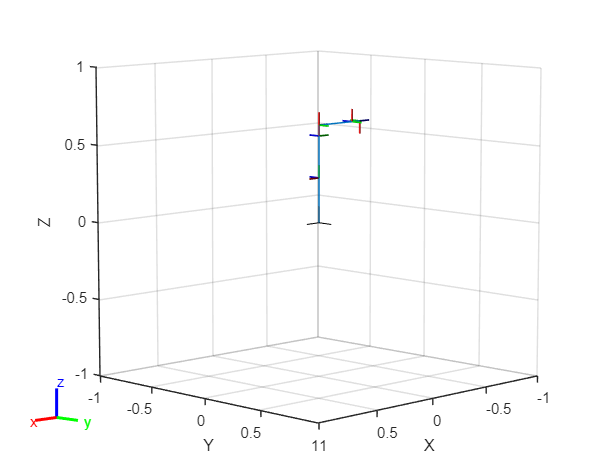

show(IRB120_DH);

### 1.2. Mediante la especificación de la posición relativa entre eslabones

Se crea el objeto *rigidBodyTree*

IRB120 = rigidBodyTree("DataFormat", "Column");

Se crea el primer rigidBody y se añade a la base del robot  sin ninguna translación/rotación. Para añadir un rigidBody:

- Crear el objeto `rigidBody` y darle un nombre único.

- Crear el objeto `rigidBodyJoint` o y darle un nombre único.

- Utilizar la función `setFixedTransform` para especificar que la transformación cuerpo a cuerpo. 

- Utilizar la función `addBody` para añadir el primer cuerpo sólido a la base del robot.

%El primer cuerpo coincide con la base
body0 = rigidBody('body0'); %Crear un objeto de sólido rígido 
jnt0 = rigidBodyJoint('jnt0','revolute');  %Crear la articulación. 
jnt0.JointAxis = [0, 0, 1];   %Eje de movimiento de la articulación. 
jnt0.PositionLimits = rango (1,:);
jnt0.HomePosition = dhparams(1,4);
tform = trvec2tform([0, 0, 0]);          
setFixedTransform(jnt0,tform); 
body0.Joint = jnt0; 
%Agregue el primer cuerpo al árbol. Especifique que lo está adjuntando a la base del árbol. La transformación fija definida anteriormente es de la base (principal) al primer cuerpo.
addBody(IRB120,body0,'base');


Crear y añadir el resto de cuerpos rigidos del robot. Se debe especificar el nombre del cuerpo rígido previo cuando se llama a la función `addBody` para añadirlo. 

%Utilizamos bucle for para construir todo el robot
n= length (dhparams); %número de cuerpos del robot
bodies = cell(n,1);
joints = cell(n,1);
for i = 1:n
    bodies{i} = rigidBody(['body' num2str(i)]);
     if i == n % El ultimo cuerpo es fijo
          joints{i} = rigidBodyJoint(['jnt' num2str(i)],"fixed");
     else
         joints{i} = rigidBodyJoint(['jnt' num2str(i)],"revolute");
         joints{i}.PositionLimits = rango (i+1,:);
     end
    
    transform = makehgtform('zrotate', dhparams(i,4)) * makehgtform('translate',[dhparams(i,1) 0 dhparams(i,3)])*makehgtform('xrotate', dhparams(i,2));
    setFixedTransform(joints{i},transform);
    bodies{i}.Joint = joints{i};
    
    if i==1
        addBody(IRB120,bodies{i},'body0')
    else
       addBody(IRB120,bodies{i},bodies{i-1}.Name)
    end
    

end

%Verificamos
showdetails(IRB120)

--------------------
Robot: (7 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body0         jnt0     revolute             base(0)   body1(2)  
   2        body1         jnt1     revolute            body0(1)   body2(3)  
   3        body2         jnt2     revolute            body1(2)   body3(4)  
   4        body3         jnt3     revolute            body2(3)   body4(5)  
   5        body4         jnt4     revolute            body3(4)   body5(6)  
   6        body5         jnt5     revolute            body4(5)   body6(7)  
   7        body6         jnt6        fixed            body5(6)   
--------------------


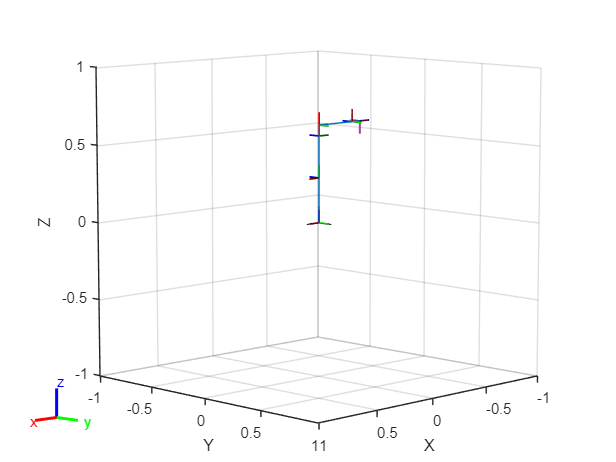

figure
show(IRB120);

### 1.3. Diferencias entre ambos métodos

Veamos las configuración por defecto:

homeConfiguration(IRB120)'

ans =      0     0     0     0     0     0


homeConfiguration(IRB120_DH)'

ans =          0    1.5708         0         0         0   -3.1416


Graficamos los robots en su configuración articular por defecto (homeConfiguration). 

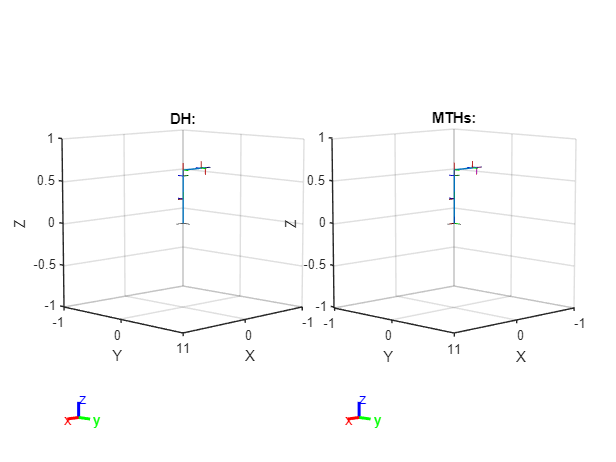

figure
subplot (1,2,1)
show(IRB120_DH);
title ('DH:')
hold on

subplot (1,2,2)
show(IRB120);
title ('MTHs:')

Calculamos la matriz de transformación homogenea del end-effector respecto a la base del robot para una configuración articular dada (q).  Para ello se utiliza la función getTransform.

En la creación del rigidbodytree mediante los parámetros DH, Matlab no considera el offset theta. Hay que incluirle para el cálculo de la transformada.

%Configuración articular
q= [4*pi/5; pi/2; -pi/4; 6*pi/8; -7/8*pi; pi/8];

MTH0 = getTransform(IRB120_DH, q+IRB120_DH.homeConfiguration, 'body6')

MTH0 =    -0.5020    0.1959   -0.8424    0.3706
   -0.7158   -0.6408    0.2775   -0.2933
   -0.4854    0.7423    0.4619    0.1592
         0         0         0    1.0000


MTH = getTransform (IRB120, q,'body6')

MTH =    -0.5020    0.1959   -0.8424    0.3706
   -0.7158   -0.6408    0.2775   -0.2933
   -0.4854    0.7423    0.4619    0.1592
         0         0         0    1.0000


Como se podía esperar, las matrices MTH son idénticas. Graficamos ambos robots en esta posición articular.

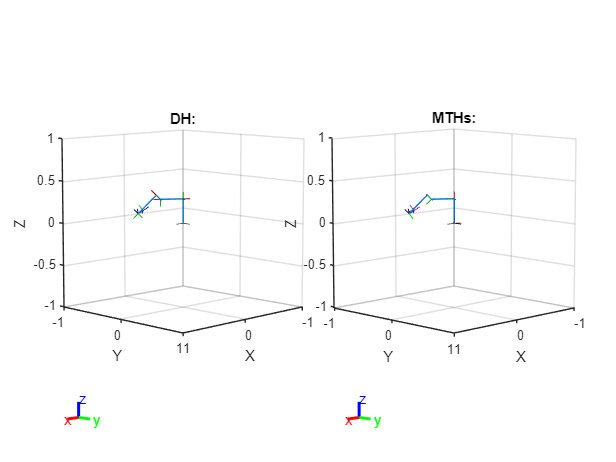

figure
subplot (1,2,1)
show(IRB120_DH, q+homeConfiguration(IRB120_DH));
title ('DH:')
hold on

subplot (1,2,2)
show(IRB120, q);
title ('MTHs:')

## 2. Diferencias 2gdl

Cargamos los robots creados en 2.2`.RigidBodyTree.mlx`

clear
load robot2gdl.mat          %rigidbodytree mediante especificación de posición relativa entre eslabones
load robot2gdl_DH.mat        %rigidbodytree mediante especificación de parámetros DH

Los dos robots son los mismos, pero creados de diferentes formas. Observamos sus detalles.

showdetails (robot2gdl)

--------------------
Robot: (3 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   tool(3)  
   3         tool         jnt3        fixed            body2(2)   
--------------------


showdetails (robot2gdl_DH)

--------------------
Robot: (2 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   tool(2)  
   2         tool         jnt2     revolute            body1(1)   
--------------------


Grafiquemos los dos robots en una posición articular q:

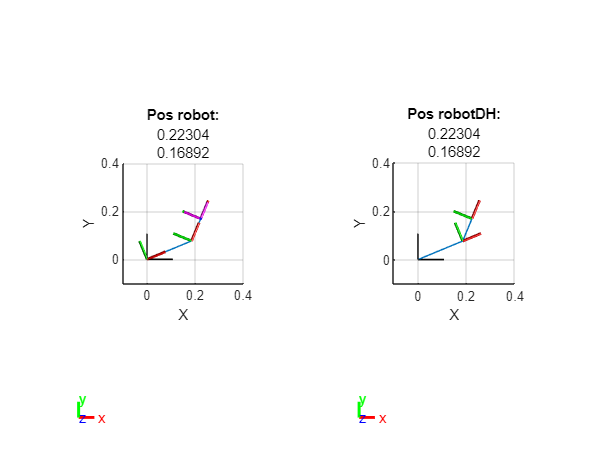

theta1 =pi/8;
theta2 = pi/4;
q=[theta1; theta2];

figure
MTH0 = getTransform(robot2gdl, q, 'tool');   %Calculo su posición en esa configuración q
pos = tform2trvec (MTH0);
subplot (1,2,1)
show(robot2gdl, q);
view (2)
ax = gca; 
ax.Projection = 'orthographic';  
axis ([-0.1 0.4 -0.1 0.4]);
title ('Pos robot:', num2str(pos(1:2)'))
hold on

subplot (1,2,2)
MTH0 = getTransform(robot2gdl_DH, q, 'tool');   %Calculo su posición en esa configuración q
pos = tform2trvec (MTH0);
show(robot2gdl_DH, q);
view (2)
ax = gca; 
ax.Projection = 'orthographic';  
axis ([-0.1 0.4 -0.1 0.4]);
title ('Pos robotDH:',  num2str(pos(1:2)'))